Consider the linear BVP  $$ u'' - (\cos x) u' + (\sin x) u = 0, \quad 0 \le x \le \pi/2, \quad u(0)=1, \; u(\pi/2)=e. $$ Its exact solution is simple.

exact = @(x) exp(sin(x));

The problem is presented in our standard form, so we can identify the coefficient functions in the ODE. Each should be coded so that they can accept either scalar or vector inputs.

p = @(x) -cos(x);
q = @(x) sin(x);
r = @(x) 0*x;      % not a scalar value!

We solve the BVP and compare the result to the exact solution.

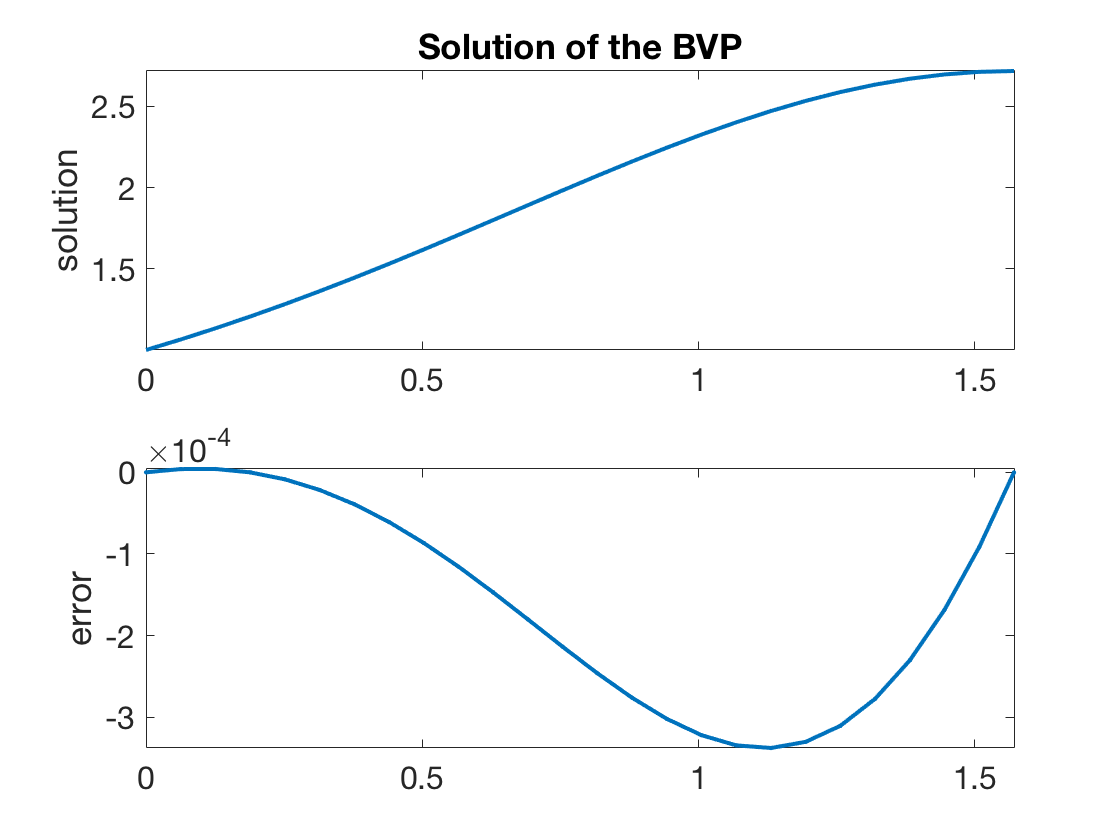

[x,u] = bvplin(p,q,r,[0 pi/2],1,exp(1),25);

subplot(2,1,1), 
plot(x,u,'-')
ylabel('solution'), axis tight     % ignore this line
title('Solution of the BVP')   % ignore this line
subplot(2,1,2)
plot(x,exact(x)-u,'.-')
ylabel('error'), axis tight     % ignore this line